# Chapter 14: Sparse Recovery from Linear Observations

close all; clear all;

## Illustration of the success of $\ell_1
$-minimization

% generate a sparse vector together with its observation vector
N = 2000;         % ambient dimension
m = 500;          % number of observations 
s = 80;           % sparsity level
% create the sparse vector x
x = zeros(N,1);
supp = sort(randperm(N,s)); 
x(supp) = randn(s,1);
% define the observation matrix A
A = sqrt(pi/2)/m*randn(m,N); 
% produce the observation vector y 
y = A*x;

First, one verifies that the sparse vector x is exactly recovered from $y=Ax$ by $\ell_1$-minimization (the code uses CVX).

cvx_begin quiet
variable x0(N)
minimize norm(x0,1)
subject to
A*x0 == y;
cvx_end
fprintf('Recovery considered to be exact, with relative L2-error of %.2s',norm(x-x0)/norm(x))

Recovery considered to be exact, with relative L2-error of 7.24e-09

Next, one compares three different ways of solving the $\ell_1$-minimization program:

- with the objective function plainly given as the $\ell_1$-norm (as above);

- by introducing nonnegative slack vectors $z^+$ and $z^-$, so as to solve the standard-form linear program$\qquad \underset{z^+,z^- \in \mathbb{R}^N} {\rm minimize} \; \sum_{j=1}^N (z^+_j + z^-_j)
\qquad \mbox{subject to }
A(z^+ - z^-) = y, \; z^+ \ge 0, \; z^- \ge 0;$

- by introducing a slack vector $c$, so as to solve the alternative linear program$\qquad \underset{z,c \in \mathbb{R}^N}{\rm minimize} \; \sum_{j=1}^N c_j 
\qquad \mbox{subject to }
Az = y, \; -c \le z \le c.$

% plain L1-minimization 
tic;
cvx_begin quiet
variable x1(N)
minimize norm(x1,1)
subject to
A*x1 == y;
cvx_end
t1 = toc;
rel_error1 = norm(x-x1)/norm(x);
fprintf('Recovery performed in %.2f sec with relative L2-error of %.2s by plain L1-minimization',...
    t1, rel_error1)

Recovery performed in 3.56 sec with relative L2-error of 7.24e-09 by plain L1-minimization

% the standard-form linear program
tic;
cvx_begin quiet
variable z_p(N) nonnegative
variable z_m(N) nonnegative
minimize sum(z_p+z_m)
subject to
A*(z_p-z_m) == y;
cvx_end
x2 = z_p-z_m;
t2 = toc;
rel_error2 = norm(x-x2)/norm(x);
fprintf('Recovery performed in %.2f sec with relative L2-error of %.2s by the standard-form linear program',...
    t2, rel_error2)

Recovery performed in 4.20 sec with relative L2-error of 7.53e-09 by the standard-form linear program

% the alternative linear program
tic;
cvx_begin quiet
variable x3(N)
variable c(N)
minimize sum(c)  
subject to
A*x3 == y;
c >= +x3;
c >= -x3;
cvx_end
t3 = toc;
rel_error3 = norm(x-x3)/norm(x);
fprintf('Recovery performed in %.2f sec with relative L2-error of %.2s by the alternative linear program',...
    t3, rel_error3)

Recovery performed in 12.33 sec with relative L2-error of 2.62e-10 by the alternative linear program

Readers are invited to run the above cells with a different solver to see the effect on the computation times. 

Changing the solver to Mosek (if installed) is recommended to execute the time-consumming experiment below. This is done by typing: 

cvx_solver mosek

## Exploration of the influence of the number of observations 

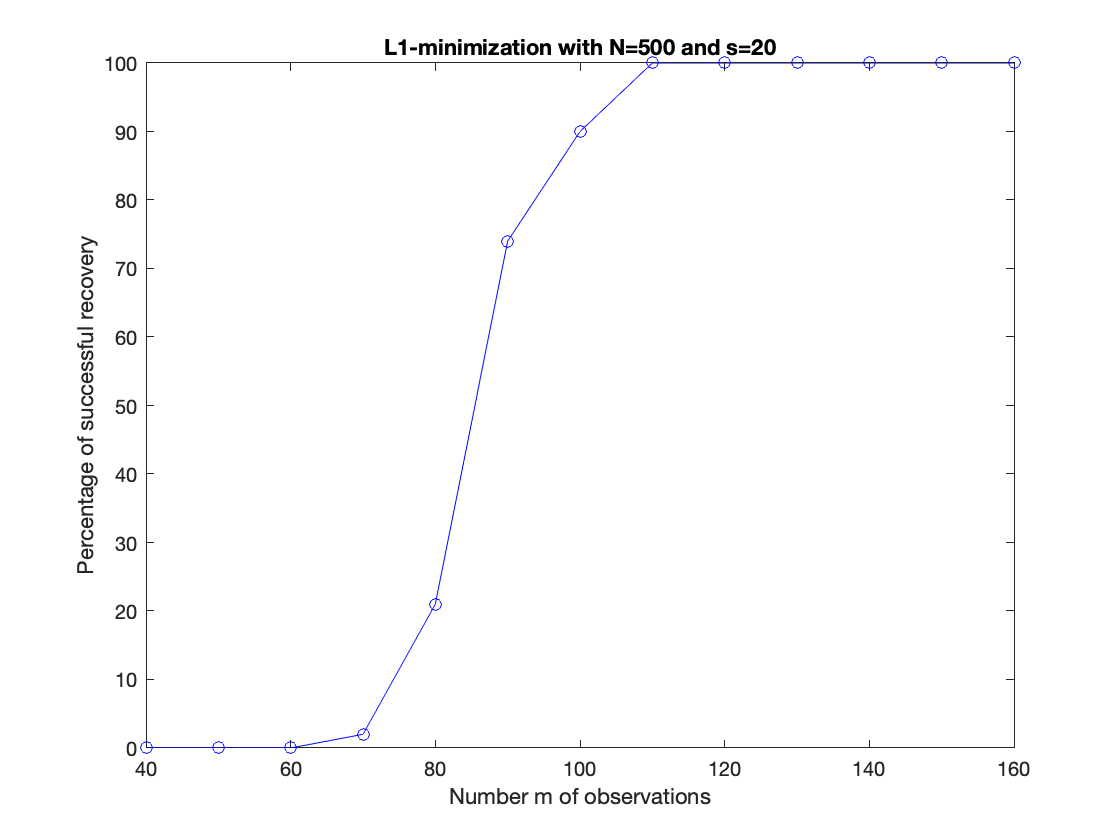

N = 500; 
s = 20; 
m_min = 2*s;
m_max = 8*s;
m_inc = 10;
n_tests = 100;
res = zeros(n_tests,m_max);
for m = m_min:m_inc:m_max
   for t = 1:n_tests
       x = zeros(N,1);
       supp = sort(randperm(N,s));
       x(supp) = randn(s,1);
       A = sqrt(pi/2)/m*randn(m,N); 
       y = A*x;
       cvx_begin quiet
       variable xstar(N)
       minimize norm(xstar,1)
       subject to
       A*xstar == y;
       cvx_end
       res(t,m) = ( norm(x-xstar) < 5e-4*norm(x) );
   end
end
plot(m_min:m_inc:m_max,100*mean(res(:,m_min:m_inc:m_max)),'b-o')
xlabel('Number m of observations')
ylabel('Percentage of successful recovery')
title(strcat('L1-minimization with N=',num2str(N),' and s=',num2str(s)))